industrialCombustion = readtable('data/industrial-combustion-processes-2010.csv');
industrialCombustion.Inquinante = string(industrialCombustion.Inquinante);

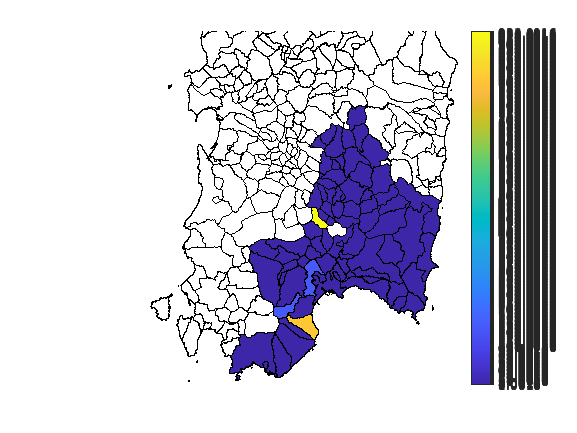

pollutants = unique(industrialCombustion.Inquinante);
currPollutant = pollutants(18);
currData = industrialCombustion(industrialCombustion.Inquinante==currPollutant, :);
map = shaperead('geo/comune-limits.shp');
% plotMap = outerjoin(map, currData, 'LeftKeys', 'nome', 'RightKeys', 'Comune', 'RightVariables', 'Valore');
% head(plotMap)

mapFigure = figure();
mapAxes = axes(mapFigure);

faceColorSpec = cell(1, height(currData)+1);
minVal = min(currData.Valore);
maxVal = max(currData.Valore);
numLevels = 32;
colorMap = parula(numLevels);
for k = 1:height(currData)
    currColLevel = 1+round(...
        (numLevels-1)*...
        ((currData.Valore(k)-minVal)/(maxVal-minVal)));
    faceColorSpec{k} = {'nome', currData.Comune{k}, 'FaceColor', colorMap(currColLevel, :)};
end
faceColorSpec{end} = {'Default', 'FaceColor', 'w'};
colorRange = makesymbolspec('Polygon', faceColorSpec{:});
plot = mapshow(map, 'DisplayType', 'Polygon', 'SymbolSpec', colorRange);
ax = plot.Parent;
ax.Visible = 'off';
title(ax, currPollutant);
ax.YLim(2) = ax.YLim(1)+((ax.YLim(2)-ax.YLim(1))/2);

tickLabels = string(minVal:maxVal);
ticks = linspace(0, 1, numel(tickLabels));
sideBar = colorbar(ax, "eastoutside", 'Ticks', ticks, 'TickLabels', tickLabels);

x = readtable('data/sarroch-co-2020.csv');
head(x)

ans = 8×13 table
    GG_Mese       gen       feb     mar     apr     mag     giu     lug     ago     set     ott     nov     dic 
    _______    _________    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

       1       {'0.980'}    1.36    0.27    0.33    0.17    0.14    0.17    0.21    0.13     0.2    0.26    0.32
       2       {'1.110'}    1.38    0.28    0.39    0.17    0.19    0.21    0.17    0.19    0.25    0.26    0.91
       3       {'1.010'}    0.72    0.36    0.54    0.18    0.15    0.17    0.18    0.12